# Plotting the 24 Welding Points

%% RKD&C - Exam 20th of January 2016. Problem 1. Kinematics
%
clc
%% First question:
% Write the code to obtain the vector with 32 points of the two
%intersecting tubes.
t=0:pi/16:2*pi;
r=15.6;
pt=[r*cos(t);r*sin(t);abs(r*cos(t));ones(1,length(t))];
%% Plotting the points in the space
%scatter3(pt(1,:),pt(2,:),pt(3,:),'r','LineWidth',2)

#### Create two tubes

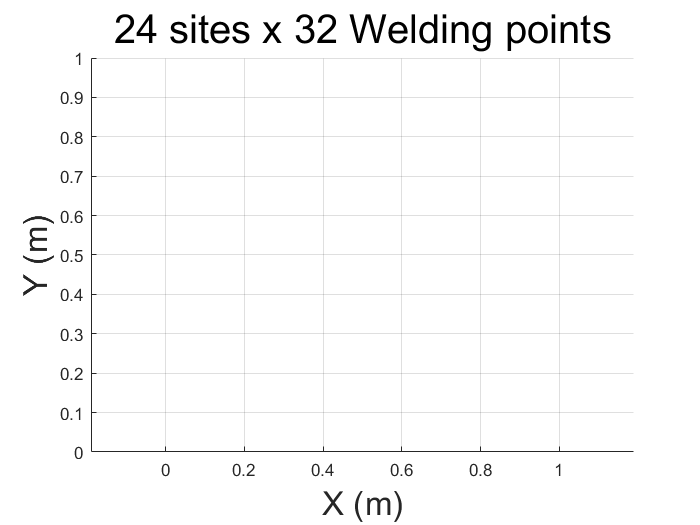

% Create xlabel
xlabel('X (m)','FontSize',20);
% Create ylabel
ylabel('Y (m)','FontSize',20);
% Create zlabel
zlabel('Z (m)','FontSize',20);
% Create title
title('24 sites x 32 Welding points','FontSize',24);
grid on;
axis equal;
hold on;

Vertical Cylinder

%% Plotting two intersecting cylinders. This was no asked
[X,Y,Z] = cylinder; % Cylinder with height (z) 1
xyz_down=[r*X(1,:);r*Y(1,:);Z(1,:);ones(1,length(X))];
xyz_up=transl(0,0,40)*xyz_down;
% Xv=[xyz_down(1,:);xyz_up(1,:)];
% Yv=[xyz_down(2,:);xyz_up(2,:)];
% Zv=[xyz_down(3,:);xyz_up(3,:)];
% %surf(Xv, Yv, Zv); 
% axis([-50 50 -50 50 -20 20]);
% %view(136,26);
% alpha(0.2);
% colormap([1 0 1]);

Horizontal cylinder

xyz_down_rot=troty(pi/2)*transl(0,0,-40)*xyz_down;
xyz_up_rot=transl(80,0,0)*xyz_down_rot;
% hold on
% Xh=[xyz_down_rot(1,:);xyz_up_rot(1,:)];
% Yh=[xyz_down_rot(2,:);xyz_up_rot(2,:)];
% Zh=[xyz_down_rot(3,:);xyz_up_rot(3,:)];
% %surf(Xh, Yh, Zh);
% %axis([-50 50 -50 50 -20 20])
% alpha(0.2);
% colormap([0 0 1]);
% view(136,26);

#### Plotting the pipes

t_z=(399.8/2)-r;
t_y=(246.6/2)-r;
xyz_down_t_r= transl(0,t_y,t_z)*trotx(-3*pi/4)*xyz_down;
xyz_up_t_r= transl(0,t_y,t_z)*trotx(-3*pi/4)*transl(0,0,80)*xyz_down;
X_t_r=[xyz_down_t_r(1,:);xyz_up_t_r(1,:)];
Y_t_r=[xyz_down_t_r(2,:);xyz_up_t_r(2,:)];  
Z_t_r=[xyz_down_t_r(3,:);xyz_up_t_r(3,:)];
surf(X_t_r, Y_t_r, Z_t_r)
%axis([-200 200 -200 200 -20 200])
alpha(0.2);
colormap([0 0 1]);
view(90,0)
xyz_down_t_r= transl(0,t_y,t_z)*xyz_down_rot;
xyz_up_t_r= transl(80,0,0)*xyz_down_t_r;
X_t_r=[xyz_down_t_r(1,:);xyz_up_t_r(1,:)];
Y_t_r=[xyz_down_t_r(2,:);xyz_up_t_r(2,:)];
Z_t_r=[xyz_down_t_r(3,:);xyz_up_t_r(3,:)];
surf(X_t_r, Y_t_r, Z_t_r);
axis([-120 120 -20 220 -20 220])
alpha(0.2);
colormap([0 0 1]);
view(90,0)

#### The 24 * 32 Welding Points

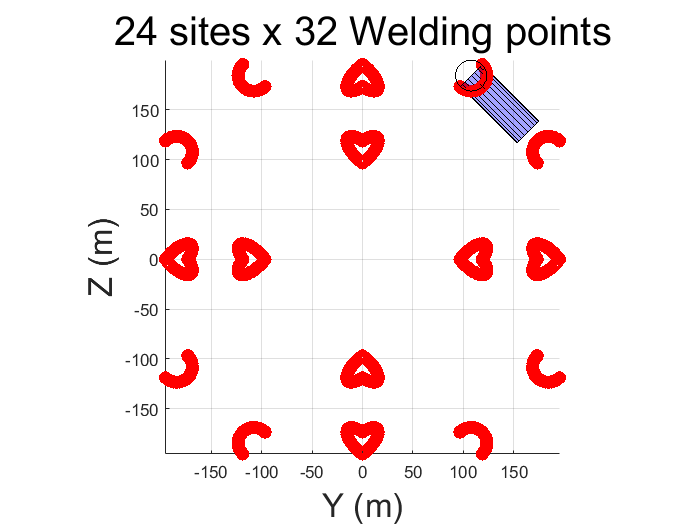

for y = [0 1]
    for x = 0:3
        for z = 0:3
            %% Plotting the n_Welding
            pt_t_r= troty(y*pi/2)*trotx(x*pi/2)*trotz(z*pi/2)*transl(0,t_y,t_z)*trotx(-3*pi/4)*pt;
            scatter3(pt_t_r(1,:),pt_t_r(2,:),pt_t_r(3,:),'r','LineWidth',2);
            pt_t_r= troty(y*pi/2)*trotx(x*pi)*trotz(z*pi/2)*trotz(pi/2)*transl(0,t_y,t_z)*trotx(-3*pi/4)*pt;
            scatter3(pt_t_r(1,:),pt_t_r(2,:),pt_t_r(3,:),'r','LineWidth',2);
            U=eye(4);
            %trplot(U, 'frame','U', 'text_opts', {'FontSize',16,'FontWeight','bold'},...
            % 'color','g','arrow','length',100,'width', 2 )
            U_W_1=trotz(z*pi/2)*transl(0,t_y,t_z)*trotx(-3*pi/4)*U;
            %trplot(U_W_1, 'frame','W#1', 'text_opts', {'FontSize',16,'FontWeight','bold'},...
            % 'color','c','arrow','length',100,'width', 2 )
            U_W_2=trotz(z*pi/2)*trotz(pi/2)*transl(0,t_y,t_z)*trotx(-3*pi/4)*U;
            %trplot(U_W_2, 'frame','W#2', 'text_opts', {'FontSize',16,'FontWeight','bold'},...
            % 'color','b','arrow','length',100,'width', 2 );
            axis tight;
            axis square 
        end
    end
end